1

% initialize question
global lambda;
lambda = 48;
r = 0.02;
b = 0.3;
h = 0.3;
T1 = 600;
T2 = 300;

nodes = gen_nodes(r,b,h);
elements = [1 2 6 5
    2 3 7 6
    3 4 8 7
    5 6 10 9
    6 7 11 10
    7 12 14 11
    7 8 13 12
    9 10 16 15
    10 11 17 16
    11 14 18 17
    ];
dbc = [1 T1
    2 T1
    3 T1
    4 T1
    12 T2
    13 T2
    14 T2
    18 T2
    ];


sol = solve_question(nodes,elements,dbc);

% display solution
display(sol(15));

  492.6434



display(sol(16));

  472.0167



display(sol(17));

  447.4502



display(sol(18));

   300



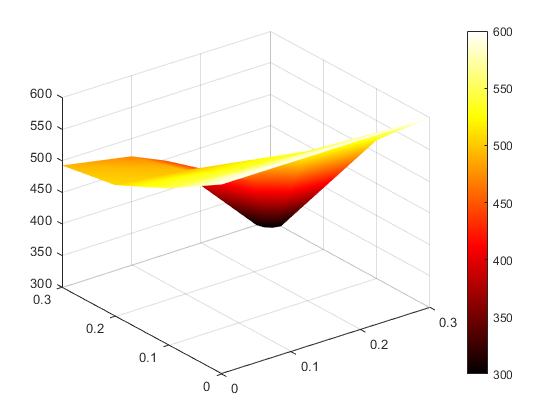

quadplot(nodes,elements,sol);
shading interp;
colormap hot;
colorbar;


sol_new = sol;
r_new = r;
while ~all(sol_new(nodes(:,2)==h)<450)
    r_new = r_new + 0.01;
    nodes_new = gen_nodes(r_new,b,h);
    sol_new = solve_question(nodes_new,elements,dbc);
end

display(sol_new(15));

  445.4779



display(sol_new(16));

  416.2657



display(sol_new(17));

  377.6438



display(sol_new(18));

   300



display(r_new);

r_new = 0.0800

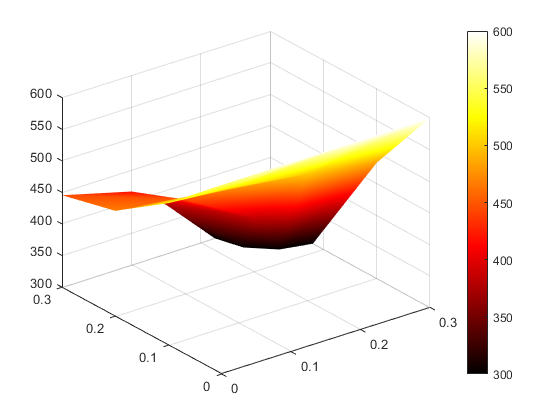

quadplot(nodes_new,elements,sol_new);
shading interp;
colormap hot;
colorbar;

function nodes = gen_nodes(r,b,h)
    nodes = zeros(18,2);
    [x, y] = meshgrid(linspace(0,b,4),linspace(0,h,4));
    nodes([1:11,15:16],:) = [y([1:11,13:14])',x([1:11,13:14])'];
    nodes(12,:)=[b-r*sin(pi/6),b-r*cos(pi/6)];
    nodes(13,:)=[b,h-r];
    nodes(14,:)=[b-r*cos(pi/6),b-r*sin(pi/6)];
    nodes(17,:)=[b/2,h];
    nodes(18,:)=[b-r,h];
end

function sol = solve_question(nodes,elements,dbc)
    % solve question
    n = 2;
    gpx = gx2dref(n);
    gpw = gw2dref(n);
    sysmat = zeros(size(nodes,1));
    rhs = zeros(size(nodes,1),1);
    for i=1:size(elements,1)
        ele = elements(i,:);
        elenodes = nodes(ele,:);
        [elemat,elevec] = evaluate_stat(elenodes,gpx,gpw);
        [sysmat,rhs] = assemble(elemat,elevec,sysmat,rhs,ele);
    end
    [sysmat,rhs] = assignDBC(sysmat,rhs,dbc);
    sol = sysmat\rhs;
end
